Allan Variance Test: Live Data Capture and Analysis from MPU6050 IMU

Author: Michael Noyce 

**Description**: 

Program to directly characterise the noise on the MPU6050. This is the first part of the program, which aims to collect data for an Allan Variance Analysis. 

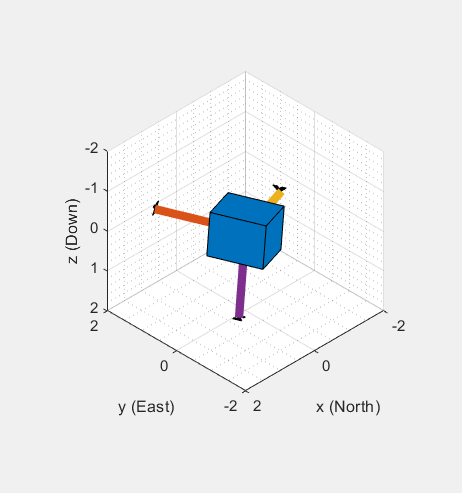

%% Clear IMU and Arduino Objects in  Workspace
clear
clear imu;
clear a; 

%Viewer Function 
%For viewer function to work: Local files HelperBox.m and
%HelperOrientationViewer.m must be in the workspace
viewer = HelperOrientationViewer;

%Create Arduino Object 
%(Arduino support package must be downloaded beforehand + Control Instrumentation Toolbox)  
a = arduino('COM9', 'Uno'); 

%Create IMU Sensor Object 
fs = 100; % Sample Rate in Hz 
imu = mpu6050(a,'SampleRate',fs,'OutputFormat','matrix'); 

%Accelerometer-Gyroscope Fusion with Kalman filter 
FUSE = imufilter('SampleRate', fs);

%Simulation and Animation 
stopTimer=100; 
ts = tic; 
while(toc(ts) < stopTimer) 
    [accel,gyro] = read(imu); 
    % Align coordinates in accordance with NED convention 
    accel = [-accel(:,1), accel(:,2), accel(:,3)]; 
    gyro = [gyro(:,1), -gyro(:,2), -gyro(:,3)]; 
    rotators = FUSE(accel,gyro); 
    for j = numel(rotators) 
      viewer(rotators(j));
    end 
end